# Intent Recognition using Vocal Recordings: Neural Network Classification based only on Raw Audio Signals

### **06/11/**2021

### Michele Ferrari [*21118273*]

## Data Import

Automatically import all `.wav` files and organize them in proper data structures.

clear; close all; clc
import_data_Kismet
import_data_BabyEars
clearvars

## Data Visualization

Use Kismet Dataset and subject CY as an example.

load kismet_WAV.mat
load babyYears_WAV.mat

### Display signal in the time domain

Example of the content of `.wav` files. It is the raw signal, as registered by the microphone.

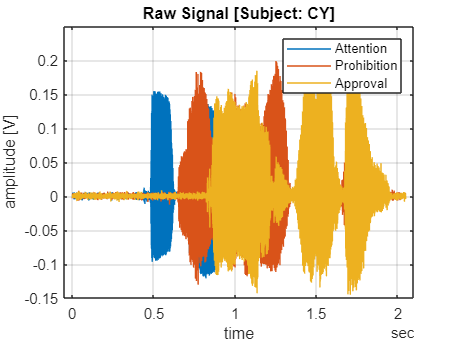

figure

data_at = kismet_WAV(1).Data;
label = kismet_WAV(1).Label;
subject = kismet_WAV(1).Subject;
plot(data_at.time, data_at.amplitude)

hold on

data_pw = kismet_WAV(5).Data;
label = kismet_WAV(5).Label;
subject = kismet_WAV(5).Subject;
plot(data_pw.time, data_pw.amplitude)

data_ap = kismet_WAV(12).Data;
label = kismet_WAV(12).Label;
subject = kismet_WAV(12).Subject;
plot(data_ap.time, data_ap.amplitude)

xlabel('time')
ylabel('amplitude [V]')
grid on
legend('Attention','Prohibition','Approval')
title(['Raw Signal [Subject: ' upper(subject) ']'])

### Basic spectral information about the wav signal

Here the Power Spectral Density and the spectrogram of the signals are displayed, in order to show the spectral differences among different classes. These informations will be used to classifiy signals.

**Attention**

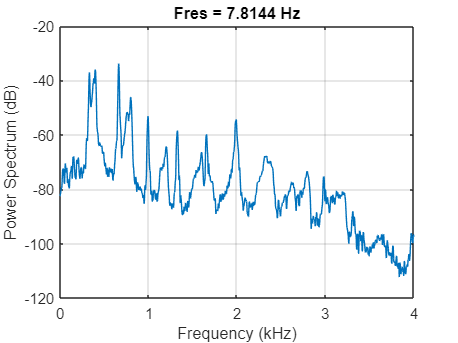

figure
show_psd_at

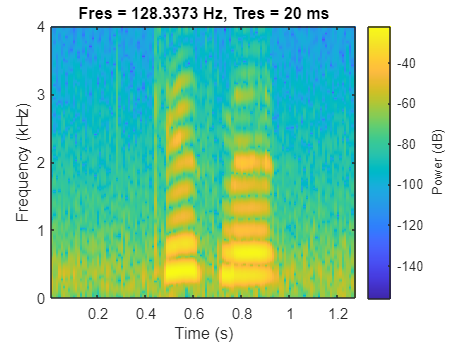

show_spectrogram_at

**Prohibition**

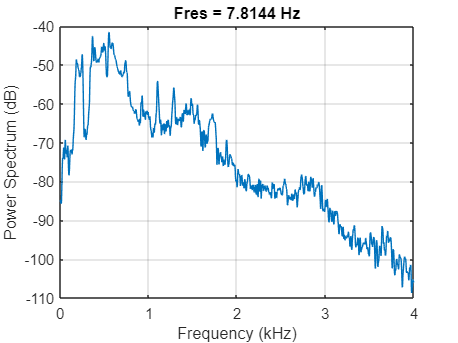

figure
show_psd_pw

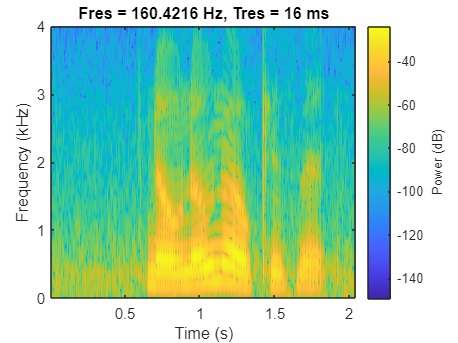

show_spectrogram_pw

**Approval**

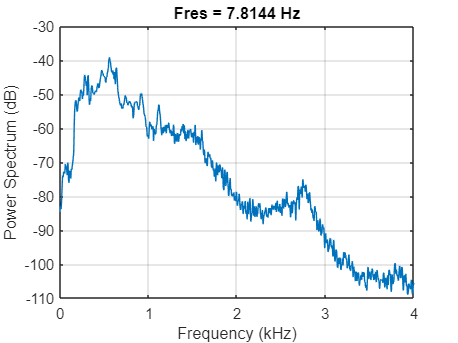

figure
show_psd_ap

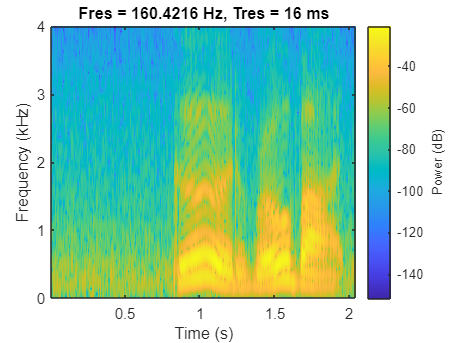

show_spectrogram_ap

### Visualize relevant features of the audio signals

*Devopedia. 2021. "Audio Feature Extraction." Version 8, May 23. Accessed 2021-09-09. *[*https://devopedia.org/audio-feature-extraction*](https://devopedia.org/audio-feature-extraction)

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",kismet_fs, ...
    "linearSpectrum",true,"mfcc",true, ...
    "spectralCentroid",true,"spectralFlatness",true, ...
    "spectralSkewness",true);

% Extract features from audio data
features = extract(extractor,data);